# Design the first order LADRC controller

## Prepare the plant

s = tf('s');
T = 10;
P = 1/(T*s-1);

## The Plant is slow and unstable for open loop running

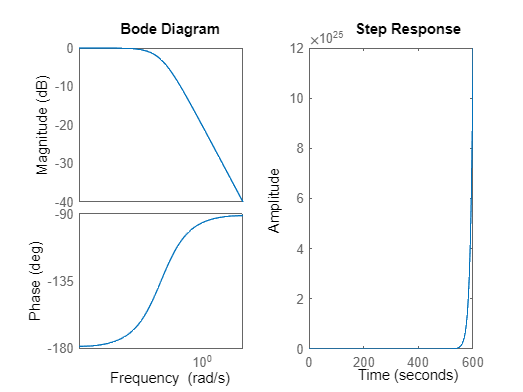

figure
subplot(1,2,1)
bode(P)
subplot(1,2,2)
step(P)

## crossover frequency wf=20 rad/s, phase margin PM=60° 

wf = 20;
PM = 60;

## Design the LADRC

Require phase compensate -29.7135
gamma : 2.1668
wo : 43.3368
wc : 9.23
b0 : 0.14366
Design result: 
PM = 60°
wf = 20 rad/s
Feedback loop BW = 4.7031 Hz
System BW = 1.5915 Hz


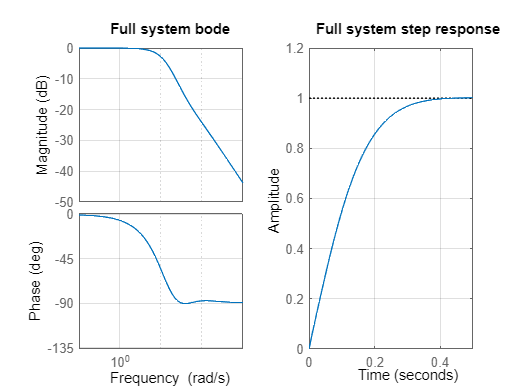

[wo, wc, b0] = DesignLADRC1(P, wf, PM);